# Control magnetically suspended ball Control Toolbox MATLAB & Simulink

## Introducing the Reference Input

clear
close all
A = [ 0   1   0
     980  0  -2.8
      0   0  -100 ]

A =          0    1.0000         0
  980.0000         0   -2.8000
         0         0 -100.0000



B = [ 0
      0
      100 ]

B =      0
     0
   100



C = [ 1 0 0 ]

C =      1     0     0


### Estabilidad en lazo abierto

poles = eig(A)

poles =    31.3050
  -31.3050
 -100.0000


### Respuesta del sistema a codiciones iniciales

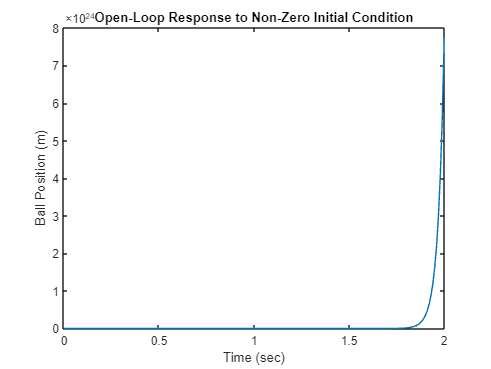


t = 0:0.01:2;
u = zeros(size(t));
x0 = [0.01 0 0];

sys = ss(A,B,C,0);

[y,t,x] = lsim(sys,u,t,x0);
plot(t,y)
title('Open-Loop Response to Non-Zero Initial Condition')
xlabel('Time (sec)')
ylabel('Ball Position (m)')

### Prueba de controlabilidad

order(sys)

ans = 3

rank(ctrb(A,B)) 

ans = 3

rank(ctrb(sys))

ans = 3

### Prueba de observabilidad

rank(obsv(A,C))

ans = 3

rank(obsv(sys))

ans = 3

### Diseño de control mediante la colocación de polos. Primer intento

p1 = -10 + 10i

p1 = -10.0000 +10.0000i

p2 = -10 - 10i

p2 = -10.0000 -10.0000i

p3 = -50

p3 = -50


K = place(A,B,[p1 p2 p3])

K =  -280.7143   -7.7857   -0.3000


sys_cl = ss(A-B*K,B,C,0)

sys_cl =
 
  A = 
              x1         x2         x3
   x1          0          1          0
   x2        980          0       -2.8
   x3  2.807e+04      778.6        -70
 
  B = 
        u1
   x1    0
   x2    0
   x3  100
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


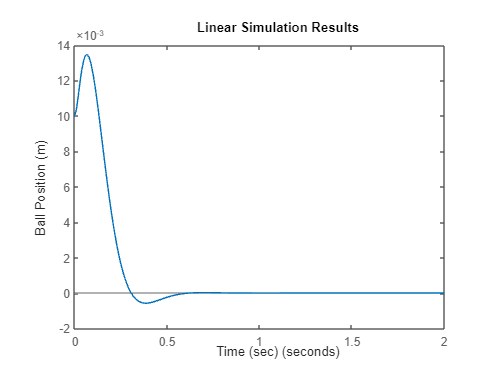


lsim(sys_cl,u,t,x0);
xlabel('Time (sec)')
ylabel('Ball Position (m)')

### Calculo del esfuerzo del control requerido

u1=-K*x';
trapz(u1)

ans = 1.3114e+28

### Diseño de control mediante la colocación de polos. Segundo intento

p1 = -20 + 20i

p1 = -20.0000 +20.0000i

p2 = -20 - 20i

p2 = -20.0000 -20.0000i

p3 = -100

p3 = -100


K = place(A,B,[p1 p2 p3])

K =  -775.7143  -20.6429    0.4000


sys_cl = ss(A-B*K,B,C,0)

sys_cl =
 
  A = 
              x1         x2         x3
   x1          0          1          0
   x2        980          0       -2.8
   x3  7.757e+04       2064       -140
 
  B = 
        u1
   x1    0
   x2    0
   x3  100
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


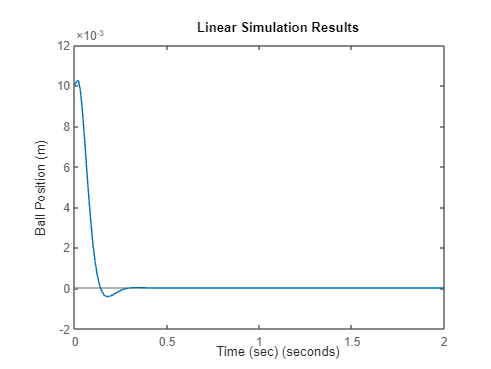


lsim(sys_cl,u,t,x0);
xlabel('Time (sec)')
ylabel('Ball Position (m)')

### Calculo del esfuerzo del control requerido

u=-K*x';
trapz(u)

ans = 3.5555e+28

## Con una entrada de referencia diferente de cero

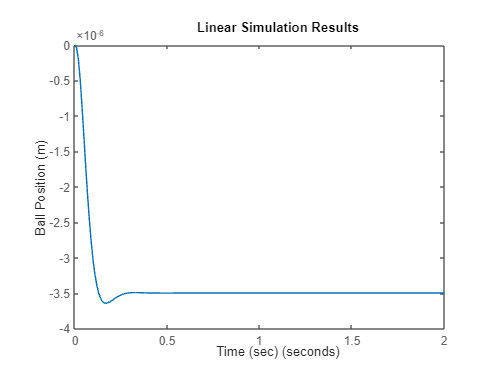

t = 0:0.01:2;
u = 0.001*ones(size(t));

sys_cl = ss(A-B*K,B,C,0);

lsim(sys_cl,u,t);
xlabel('Time (sec)')
ylabel('Ball Position (m)')
axis([0 2 -4E-6 0])

### Calculando el factor de escala para entradas de referencia diferentes de cero

Nbar = rscale(sys,K)

Nbar = -285.7143

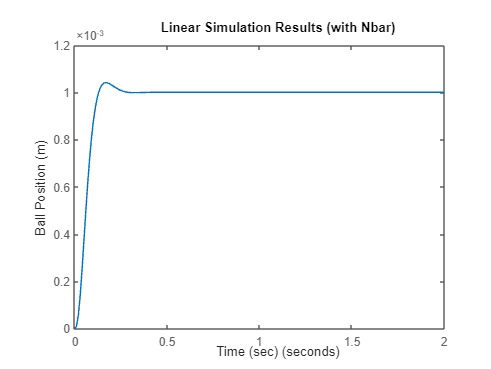

lsim(sys_cl,Nbar*u,t)
title('Linear Simulation Results (with Nbar)')
xlabel('Time (sec)')
ylabel('Ball Position (m)')
axis([0 2 0 1.2*10^-3])